# RoboCup 2024 Qualifier submission

## Connecting to ROS enabled machine

rosIP = "192.168.8.158"; % My IP address!  
rosshutdown; 
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_30556 with NodeURI http://192.168.8.89:56804/ and MasterURI http://192.168.8.158:11311.


## Enabling all ROS connections and robot info

run ros_connections.m
run load_robot.m

## Fixed objects on right hand side

We will look at the fixed on the right hand side of the robotic arm first 

%Loading locations
run fixed_right_matrices.m
open_grip_pos = 0.01;

fprintf('Getting rid of fixed objects on the right hand side');

for i = 4:size(translation_matrix,1)
    %Reset the arm
    run right_side_init.m
    gripGoal=packGripGoal(open_grip_pos,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    fprintf('Arm reset for Obj num: %d', i);

    %Extract info from the matrices
    object_location = translation_matrix(i,:);
    grip_orient = rotation_matrix(i,:);
    object_type = object_matrix(i);

    %Approaching the object
    gripperTranslation = object_location; 
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    fprintf("Arm at the object")

    %Grab the object
    if strcmp(object_type, 'bottle_grip')
        grip_value = 0.517;
    elseif strcmp(object_type, 'can_grip')
        grip_value = 0.24;
    else
        error('Unrecognized grip type');
    end

    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    
    run robot_delay.m
    fprintf("Object grabbed")

    %Drop the object based on the object type
    if object_type == "bottle_grip"
        run bottle_drop.m
    else
        run can_drop.m
    end

    run robot_delay.m
    fprintf("Object dropped")

end

## Fixed object on left hand side 

%Loading locations
run fixed_left_matrices.m
open_grip_pos = 0.01;

fprintf('Getting rid of fixed objects on the left hand side');

for i = 5:size(translation_matrix,1)
    %Reset the arm
    run left_side_init.m
    gripGoal=packGripGoal(open_grip_pos,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    fprintf('Arm reset for Obj num: %d', i);

    %Extract info from the matrices
    object_location = translation_matrix(i,:);
    grip_orient = rotation_matrix(i,:);
    object_type = object_matrix(i);

    %Approaching the object
    gripperTranslation = object_location; 
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    fprintf("Arm at the object")

    %Grab the object
    if strcmp(object_type, 'bottle_grip')
        grip_value = 0.517;
    elseif strcmp(object_type, 'can_grip')
        grip_value = 0.25;
    else
        error('Unrecognized grip type');
    end

    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    
    run robot_delay.m
    fprintf("Object grabbed")

    %Drop the object based on the object type
    if object_type == "bottle_grip"
        run bottle_drop.m
    else
        run can_drop.m
    end

    run robot_delay.m
    fprintf("Object dropped")

end

## Use of RGB and Depth sensor for classification

In this section, we will identify the color of the center object and then move onto another object determining whether it is can or bottle

Identify the color of center object

run right_side_init.m

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


run sensor_arm_set.m %resetting the arm 

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


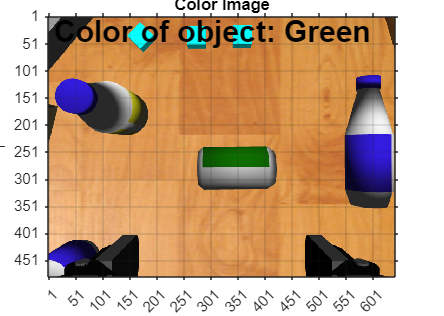

Color of object: Green


% Define region of interest
region = [240, 275, 300, 400]; % [y_start, y_end, x_start, x_end]

% Initialize figures for display
colorFig = figure('Name', 'Color Image');

try
    % Receive the color image
    colorMsg = receive(colorImageSub, 10); % Timeout after 10 seconds
    colorImage = readImage(colorMsg);

    % Display the color image
    figure(colorFig);
    imshow(colorImage);
    title('Color Image');

    % Add dynamic axis with variable tick spacing
    axis on;
    [height, width, ~] = size(colorImage);
    xlim([0.5, width + 0.5]);
    ylim([0.5, height + 0.5]);

    % Determine tick spacing based on default tickStep
    tickStep = 50;
    xLim = get(gca, 'XLim');
    yLim = get(gca, 'YLim');
    xTickSpacing = tickStep * diff(xLim) / width;
    yTickSpacing = tickStep * diff(yLim) / height;

    % Set dynamic ticks
    xTicks = round(xLim(1)):xTickSpacing:round(xLim(2));
    yTicks = round(yLim(1)):yTickSpacing:round(yLim(2));
    set(gca, 'XTick', xTicks, 'YTick', yTicks);
    grid on;

    xlabel('X');
    ylabel('Y');

    % Extract the region of interest
    regionColor = colorImage(region(1):region(2), region(3):region(4), :);
    
    % Separate the color channels
    redChannel = regionColor(:, :, 1);
    greenChannel = regionColor(:, :, 2);
    blueChannel = regionColor(:, :, 3);
    
    % Calculate the total counts of each color
    redCount = sum(redChannel(:));
    greenCount = sum(greenChannel(:));
    blueCount = sum(blueChannel(:));
    
    % Calculate the count for yellow (red + green)
    yellowCount = sum(redChannel(:) & greenChannel(:));
    
    % Store the counts in an array
    colorCounts = [redCount, greenCount, blueCount, yellowCount];
    
    % Find the maximum count and its index
    [maxCount, maxIndex] = max(colorCounts);
    
    % Define the color names
    colors = {'Red', 'Green', 'Blue', 'Yellow'};
    
    % Determine the most visible color
    mostVisibleColor = colors{maxIndex};

    % Display the result on the figure
    text(10, 30, ['Color of object: ', mostVisibleColor], 'Color', 'black', 'FontSize', 20, 'FontWeight', 'bold');

    %Print the result
    fprintf('Color of object: %s\n', mostVisibleColor);   

catch ME
    disp('Error receiving or displaying RGB image:');
    disp(ME.message);
end

Classify the left object as can or bottle based on height

run left_side_init.m

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


%setting the arm above the object
gripperTranslation = [-0.15 0.405 0.6]; 
gripperRotation = [pi -pi 0]; 
tform = eul2tform(gripperRotation); 
tform(1:3,4) = gripperTranslation'; 
[configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
trajGoal = packTrajGoal(configSoln,trajGoal); 
sendGoal(trajAct,trajGoal); 
run robot_delay.m

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


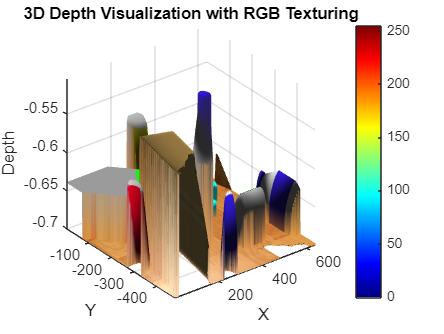

Maximum depth in the region of interest: -0.50 meters


It is a bottle


% Define region of interest
region = [1, 400, 1, 400]; % [y_start, y_end, x_start, x_end]

% Initialize figures for display
depthFig = figure('Name', '3D Depth Visualization');

% Receive the depth image
try
    depthMsg = receive(depthImageSub, 10); % Timeout after 10 seconds
    depthImage = readImage(depthMsg);
    colorMsg = receive(colorImageSub, 10); % Timeout after 10 seconds
    colorImage = readImage(colorMsg);

    % Convert the depth image to double for visualization
    depthData = double(depthImage);

    % Negate the depth data for correct axis display
    depthData = -depthData;
    
    % % depthData = round(depthData, 3); % Round to 3 decimal places

    % Display the 3D depth visualization with RGB texture
    figure(depthFig);
    [X, Y] = meshgrid(1:size(depthData, 2), 1:size(depthData, 1));
    Y = -Y; % Flip Y axis
    surf(X, Y, depthData, 'FaceColor', 'texturemap', 'CData', colorImage, 'EdgeColor', 'none');
    colormap('jet'); % Apply color map
    colorbar; % Display color bar
    title('3D Depth Visualization with RGB Texturing');
    xlabel('X');
    ylabel('Y');
    zlabel('Depth');
    view(3); % Set the view to 3D
    axis tight;
    shading interp; % Interpolate shading for smoother visualization

    % Calculate and display the maximum depth in the region
    regionDepth = depthData(region(1):region(2), region(3):region(4));
    maxDepth = max(regionDepth(:));
    fprintf('Maximum depth in the region of interest: %.2f meters\n', maxDepth);
    
    %Classifying as bottle or can
    if maxDepth > -0.51
        fprintf('It is a bottle\n');
    else
        fprintf('It is a can\n');
    end

catch ME
    disp('Error receiving or displaying Depth image:');
    disp(ME.message);
end

## Shape change region

We will get rid of the items in the shape change region using the sensors

run yellow_region_matrices.m

fprintf('Getting rid of objects in yellow region');

for i = 5:size(translation_matrix,1)
    %Reset the arm
    run left_side_init.m
    gripGoal=packGripGoal(open_grip_pos,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    % fprintf('Arm reset for Obj num: %d', i);

    %Extract info from the matrices
    object_location = translation_matrix(i,:);
    grip_orient = rotation_matrix(i,:);
    regionOfInterest = obj_regions(i).values;

    %Approaching the object
    gripperTranslation = object_location; 
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    fprintf("Arm above the object")

    %Now we go down based on the object
    %Note: bottle and can have same height if they are lying down
    if i <= 2
        %first two objects we approach are lying down objects
        dist_obj = 0.02;
        object_orient = 'down';
        object_type = object_checker(regionOfInterest);
        gripperTranslation(3) = gripperTranslation(3) - 0.07;
        if strcmp(object_type, "bottle_grip")
            gripperTranslation(2) = gripperTranslation(2) + 0.01; %to stabilize when picking up bottle
        end
    else
        %we use depth sensor to figure out the type of object and move
        %accordingly
        object_orient = 'up';
        object_type = object_checker(regionOfInterest);
        if strcmp(object_type,'bottle_grip')
            gripperTranslation(3) = 0.24;
        else
            gripperTranslation(3) = 0.13;
        end
    end

    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    fprintf("Arm at the object")

    %Grab the object
    if strcmp(object_orient, 'down')
        grip_value = can_grip;
    elseif strcmp(object_type, 'bottle_grip')
        grip_value = bottle_grip;
    elseif strcmp(object_type, 'can_grip')
        grip_value = can_grip;
    else
        error('Unrecognized grip type');
    end

    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    
    run robot_delay.m
    fprintf("Object grabbed")

    %Drop the object based on the object type
    if object_type == "bottle_grip"
        run bottle_drop.m
    else
        run can_drop.m
    end

    run robot_delay.m
    fprintf("Object dropped")

end

## Pouches

In this section, we will pick all the pouches, put them on the scale and then the bin

run pouch.m

fprintf('Getting rid of the pouches');

Getting rid of the pouches


for i = 1:size(translation_matrix,1)
    %Reset the arm based on pouch
    if i == 6
        run right_side_init.m
    else 
        run left_side_init.m
    end
    gripGoal=packGripGoal(open_grip_pos,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    % fprintf('Arm reset for pouch num: %d', i);

    %Extract info from the matrices
    object_location = translation_matrix(i,:);
    grip_orient = rotation_matrix(i,:);
    object_type = "pouch_grip";

    %Approaching the object
    gripperTranslation = object_location; 
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    fprintf("Arm at the pouch")

    %Now we will go up and down to fix the pouch
    %Pulling the pouch towards
    gripperTranslation(2) = gripperTranslation(2)-correction_parameter;
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m
    %Pushing the pouch
    gripperTranslation(2) = gripperTranslation(2)+correction_parameter;
    gripperRotation = grip_orient; 
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m

    %Grab the object
    grip_value = pouch_grip;
    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    fprintf("Pouch grabbed")

    %Reset the arm
    run left_side_init.m

    %Go to weighing scale
    gripperTranslation = drop_location;
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m

    %Drop
    grip_value = open_grip_pos;
    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    fprintf("Pouch Dropped on scale")

    %Go to pick up location
    gripperTranslation = pick_location;
    tform = eul2tform(gripperRotation); 
    tform(1:3,4) = gripperTranslation'; 
    [configSoln, ~] =ik('tool0',tform,ikWeights,initialIKGuess);
    trajGoal = packTrajGoal(configSoln,trajGoal); 
    sendGoal(trajAct,trajGoal); 
    run robot_delay.m

    %Grab the object
    grip_value = pouch_grip;
    gripGoal=packGripGoal(grip_value,gripGoal);
    sendGoal(gripAct,gripGoal);
    run robot_delay.m
    fprintf("Pouch picked from scale")

    %Drop the pouch
    run can_drop.m
    run robot_delay.m
    fprintf("Pouch dropped in bin")

end

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Arm at the pouch

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Pouch grabbed

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Pouch Dropped on scale

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Pouch picked from scale

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Pouch dropped in bin

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Arm at the pouch

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Pouch grabbed

Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
Completed


Waiting for Trajectory execution to complete...
Trajectory execution succeeded.
